# Electricity Statistics

Load price and usage data, and compute revenue.

load electricity
revenue = price.*usage;

Calculate revenue in 2015 dollars.

revenue2015 = revenue.*dollar2015;

#### Plot annual min, max, and average usage

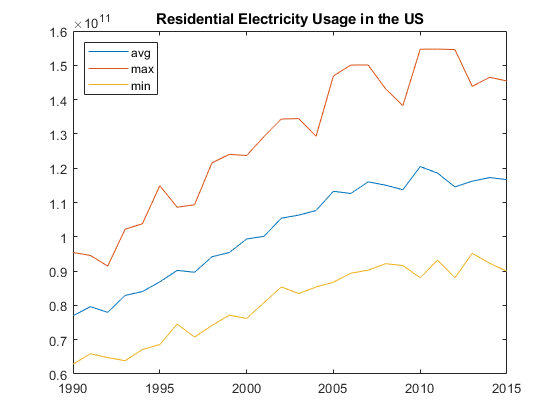

annual = mean(usage);
plot(yr,annual)
hold on
plot(yr,max(usage))
plot(yr,min(usage))
hold off
legend("avg","max","min","Location","northwest")
title("Residential Electricity Usage in the US")

#### Plot average usage by month

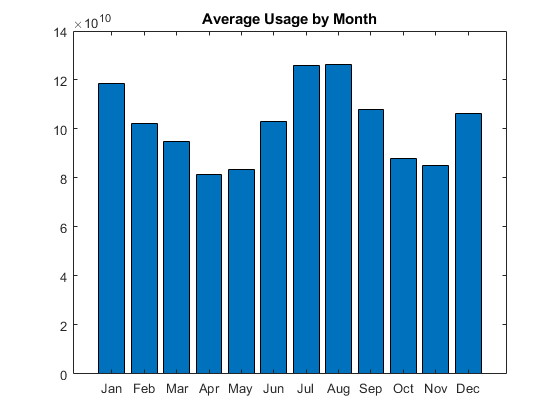

monthly = mean(usage,2);
bar(mth,monthly)
title("Average Usage by Month")
xticks(1:12)
mthNames = month(datetime(2000,1:12,1),'shortname');
xticklabels(mthNames)

#### Plot median year-over-year growth in revenue

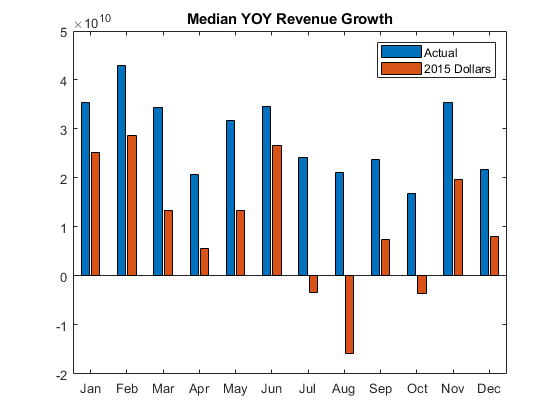

YoY = diff(revenue,[],2);
medYoY = median(YoY,2);
YoY2015 = diff(revenue2015,[],2);
medYoY2015 = median(YoY2015,2);
bar(mth,[medYoY medYoY2015])
xticks(1:12)
xticklabels(mthNames)
legend("Actual","2015 Dollars")
title("Median YOY Revenue Growth")